% -----------------------------------------
% Data IO
% LiXin
% 2022/2/18
% -----------------------------------------

Problem 1

clear; close; clc;

(1)

syms x y a b z
eqn1=3*x^2+7*x*y+4==0

$$eqn1 = 3\,x^{2}+7\,y\,x+4=0$$

eqn2=a*y+b*x==z

$$eqn2 = a\,y+b\,x=z$$

eqn3=x-2*y+2*z==0

$$eqn3 = x-2\,y+2\,z=0$$

(2)

eqn1_x=solve(eqn1)

$$eqn1\_x = \left(\begin{array}{c} -\frac{7\,y}{6}-\frac{\sqrt{49\,y^{2}-48}}{6}\\ \frac{\sqrt{49\,y^{2}-48}}{6}-\frac{7\,y}{6} \end{array}\right)$$

eqn2_x=solve(eqn2)

$$eqn2\_x = \frac{z-a\,y}{b}$$

eqn3_x=solve(eqn3)

$$eqn3\_x = 2\,y-2\,z$$

(3)

S=solve([eqn1 eqn2 eqn3],x,y,z);
x=S.x

$$x = \left(\begin{array}{c} -2\,\sqrt{2}\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}}\,\left(a-1\right)\\ 2\,\sqrt{2}\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}}\,\left(a-1\right) \end{array}\right)$$

y=S.y

$$y = \left(\begin{array}{c} \sqrt{2}\,\left(2\,b+1\right)\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}}\\ -\sqrt{2}\,\left(2\,b+1\right)\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}} \end{array}\right)$$

z=S.z

$$z = \left(\begin{array}{c} \sqrt{2}\,\left(a+2\,b\right)\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}}\\ -\sqrt{2}\,\left(a+2\,b\right)\,\sqrt{\frac{1}{\left(a-1\right)\,\left(14\,b-6\,a+13\right)}} \end{array}\right)$$

(4)

a=4;
b=0.3;
S=subs(S);
x=S.x

$$x = \left(\begin{array}{c} -\frac{\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{17}\\ \frac{\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{17} \end{array}\right)$$

y=S.y

$$y = \left(\begin{array}{c} \frac{4\,\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{255}\\ -\frac{4\,\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{255} \end{array}\right)$$

z=S.z

$$z = \left(\begin{array}{c} \frac{23\,\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{510}\\ -\frac{23\,\sqrt{2}\,\sqrt{5}\,\sqrt{102}\,\mathrm{i}}{510} \end{array}\right)$$

(5)

x=double(x)

x =    0.0000 - 1.8787i
   0.0000 + 1.8787i


y=double(y)

y =    0.0000 + 0.5010i
   0.0000 - 0.5010i


z=double(z)

z =    0.0000 + 1.4403i
   0.0000 - 1.4403i


Problem 2

clear; close; clc;

(1)

y=poly2sym([0.3 0 0 -3 4.1 -5])

$$y = \frac{3\,x^{5}}{10}-3\,x^{2}+\frac{41\,x}{10}-5$$

D1=diff(y,1)

$$D1 = \frac{3\,x^{4}}{2}-6\,x+\frac{41}{10}$$

D2=diff(y,2)

$$D2 = 6\,x^{3}-6$$

I=int(y)

$$I = \frac{x^{6}}{20}-x^{3}+\frac{41\,x^{2}}{20}-5\,x$$

(2)

figure
subplot(2,2,1)
ezplot(y,[-4 4]), legend('the polynomial')
subplot(2,2,2)
ezplot(D1,[-4 4]), legend('first derivative')
subplot(2,2,3)
ezplot(D2,[-4 4]), legend('second derivative')
subplot(2,2,4)
ezplot(I, [-4 4]), legend('Integral')

(3)

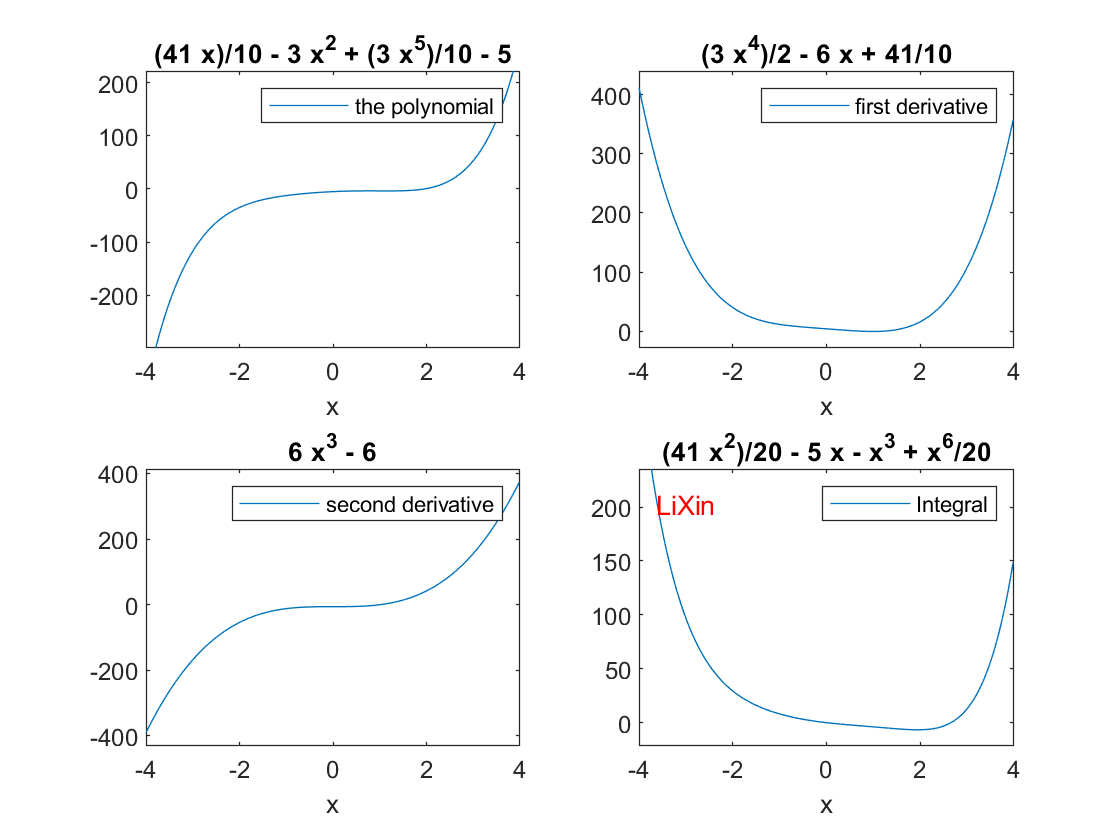

placeMyName(1)

Problem 3

clear; close; clc;

(1)

T=readtable('dotData.txt','Delimiter',',');
x=T.Var1;
y=T.Var2;
size=T.Var3;

(2)

figure
for i = 1:length(x)
    if size(i) == 0.5
        rectangle('Position',[x(i) y(i) size(i) size(i)], 'Curvature',[1 1], 'FaceColor', 'red','EdgeColor','red')
    else
        rectangle('Position',[x(i) y(i) size(i) size(i)], 'Curvature',[1 1], 'FaceColor', 'black','EdgeColor','black')
    end
end

(3) ealge

(4)

set(gca, 'xtick', [])
set(gca, 'ytick', [])

(5)

placeMyName(1)

(6)

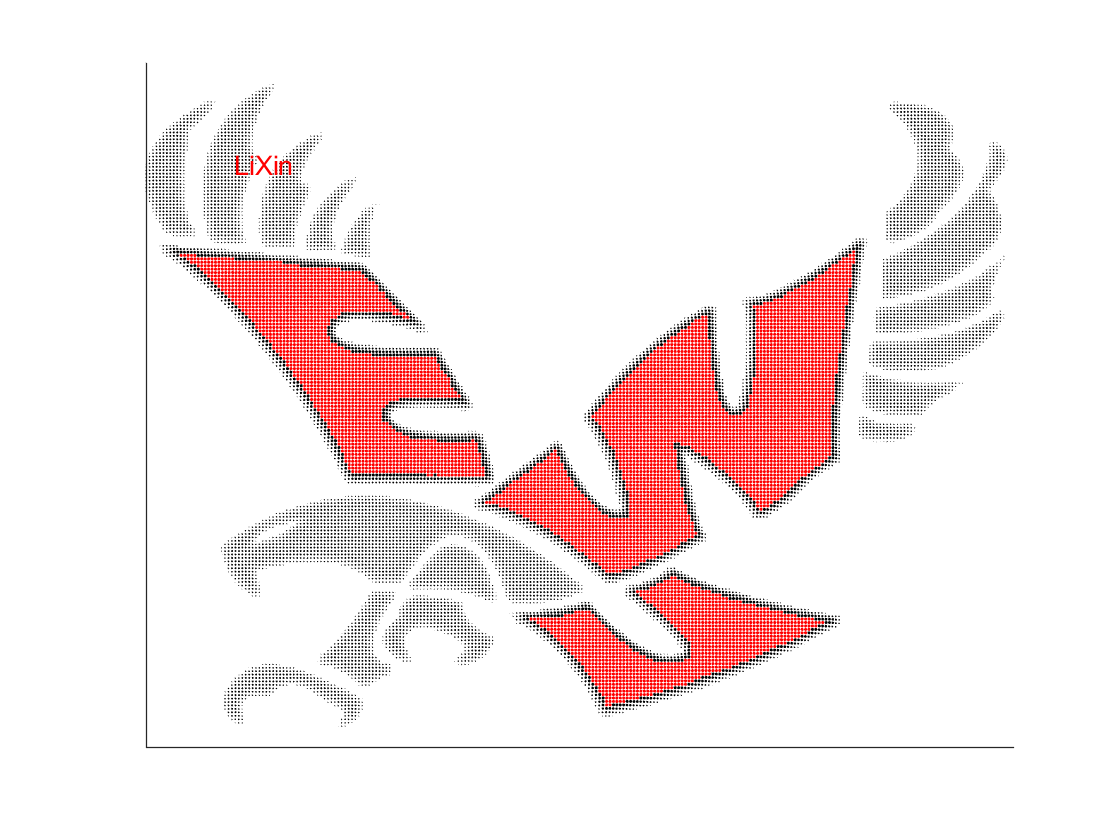

axis equal

(7)~(8)

already modified

Problem 4

clear; close; clc;

(1)

(a)

x=0:10:360

x =      0    10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200   210   220   230   240   250   260   270   280   290   300   310   320   330   340   350   360


(b)

y=sind(x)

y =          0    0.1736    0.3420    0.5000    0.6428    0.7660    0.8660    0.9397    0.9848    1.0000    0.9848    0.9397    0.8660    0.7660    0.6428    0.5000    0.3420    0.1736         0   -0.1736   -0.3420   -0.5000   -0.6428   -0.7660   -0.8660   -0.9397   -0.9848   -1.0000   -0.9848   -0.9397   -0.8660   -0.7660   -0.6428   -0.5000   -0.3420   -0.1736         0


(c)

theta=0

theta = 0

(d)

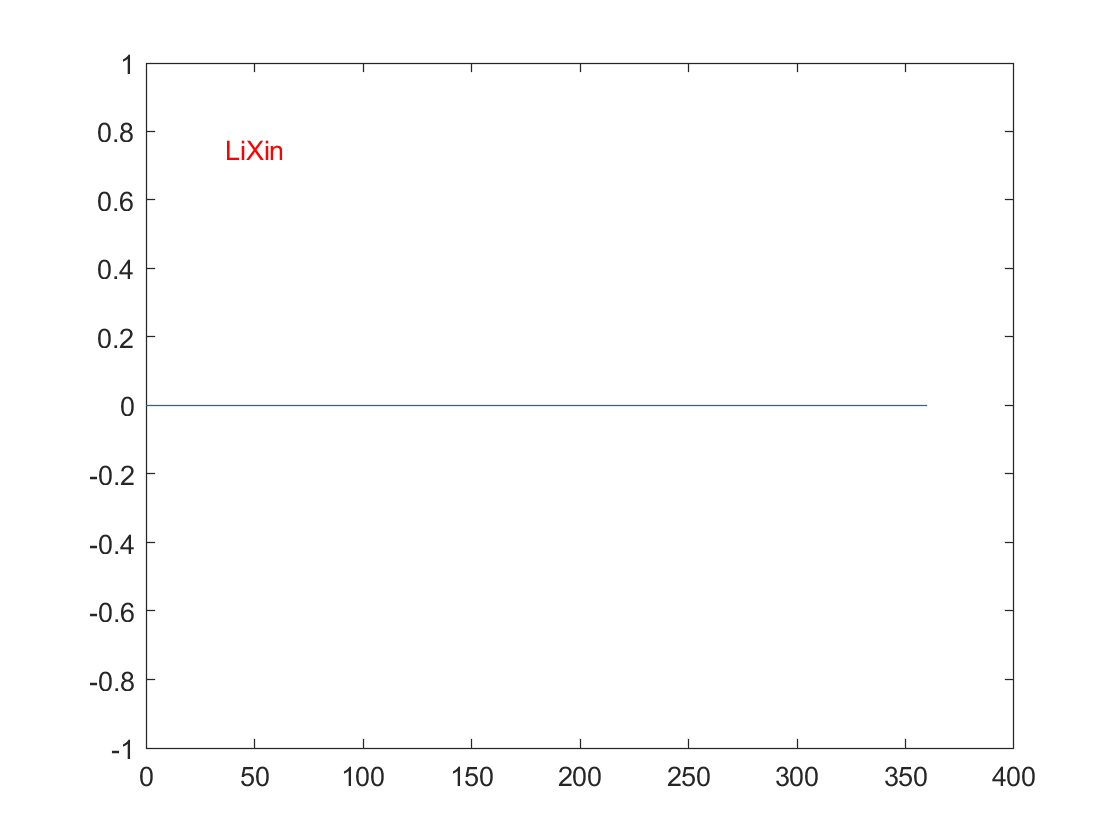

loops = 73;
M(loops) = struct('cdata',[],'colormap',[]);
i=1;
while true
    y_plot=y*sind(theta);
    plot(x,y_plot);
    ylim([-1 1])
    placeMyName(1);
    pause(0.1);
    M(i)=getframe;
    i=i+1;
    theta=theta+10;
    if theta > 720
        break;
    end
end

(2)

v1=VideoWriter('all.avi');
open(v1);
writeVideo(v1,M);
close(v1);
% write gif
fig=figure;
idx=1;
for theta = 0 : 10 : 90
    y_plot=y*sind(theta);
    plot(x,y_plot);
    ylim([-1 1])
    placeMyName(1);
    drawnow
    frame = getframe(fig);
    im{idx} = frame2im(frame);
    idx=idx+1;
end

nImages=10;
close;
filename = 'frames10.gif'; % Specify the output file name
for idx = 1:nImages
    [A,map] = rgb2ind(im{idx},256);
    if idx == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',0.1);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',0.1);
    end
end

Problem 5

clear; close; clc;

(1)

%num=input('enter a number between 20 and 100');
num=35;

(2)

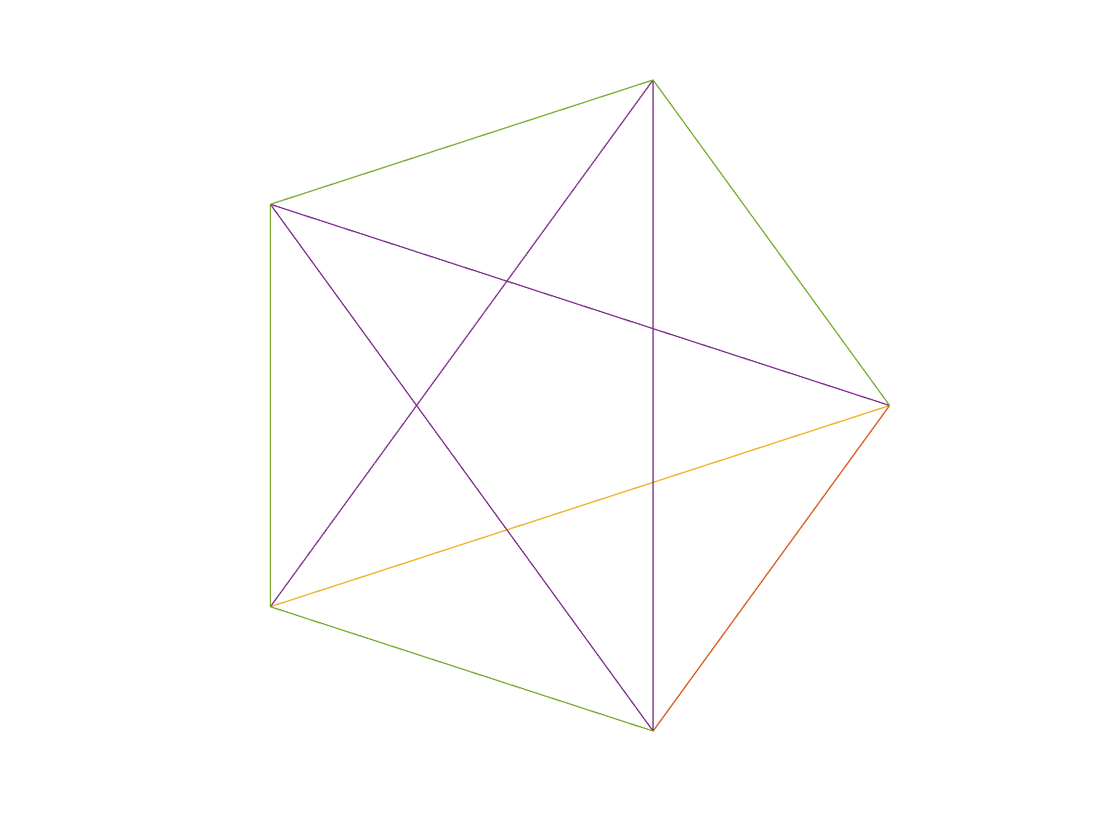

k=5;
flag=1; % forward
while true
    plot(fft(eye(k)));
    axis([-1 1 -1 1])
    pause(0.05);
    if(flag)
        k=k+2;
    else
        k=k-2;
    end
    if(k > num)
        flag=0;
    end
    if(~flag && k < 5)
        break
    end
end
axis equal
axis off

function placeMyName(x)
    ax=gca;
    name='LiXin';
    x_interval=(ax.XLim(2)-ax.XLim(1))/8;
    y_interval=(ax.YLim(2)-ax.YLim(1))/8;
    switch x
        case 1 % upper left
            text(ax.XLim(1)+x_interval,ax.YLim(2)-y_interval,name,'HorizontalAlignment',"center", 'Color',[1 0 0])
        case 2 % upper right
            text(ax.XLim(2)-x_interval,ax.YLim(2)-y_interval,name,'HorizontalAlignment',"center")
        case 3 % lower left
            text(ax.XLim(1)+x_interval,ax.YLim(1)+y_interval,name,'HorizontalAlignment',"center")
        case 4 % lower right
            text(ax.XLim(2)-x_interval,ax.YLim(1)+y_interval,name,'HorizontalAlignment',"center")
    end
end